# ASE387P Homework 3

## Problem 1

clear; clc

### Part a-b

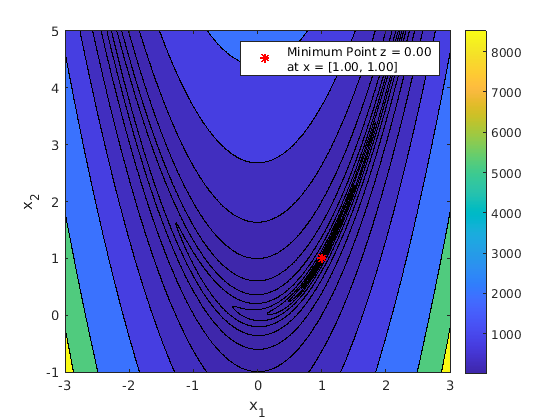

f = @(x) (1-x(1))^2 + 100*(x(2)-x(1)^2)^2;
del = 0.01;
x1 = -3:del:3;
x2 = -1:del:5;
z = zeros(length(x1));
for i = 1:length(x1)
    for j = 1:length(x1)
        z(j, i) = f([x1(i), x2(j)]); 
    end
end
contourf(x1, x2, z, [logspace(-4, 5, 22), max(max(z))*0.85], 'HandleVisibility',"off")
colorbar
[val, idx1] = min(z);
[val, idx2] = min(val);
idx1 = idx1(idx2);
hold on
scatter(x1(idx2), x2(idx1), 'r*', 'DisplayName', ...
    sprintf('Minimum Point z = %0.2f \nat x = [%0.2f, %0.2f]', val, x1(idx2), x2(idx1)), ...
    'linewidth', 1.5)
legend
hold off
xlabel('x_1'); ylabel('x_2')
exportgraphics(gcf, 'hw3p1a.png', 'Resolution', 200)

### Part c

syms x_1 x_2
f_sym = (1-x_1)^2 + 100*(x_2-x_1^2)^2

$$f\_sym = {\left(x_{1}-1\right)}^{2}+100\,{\left(x_{2}-{x_{1}}^{2}\right)}^{2}$$

eqs = [diff(f_sym, x_1) == 0; diff(f_sym, x_2) == 0]

$$eqs = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2=0\\ 200\,x_{2}-200\,{x_{1}}^{2}=0 \end{array}\right)$$

sol = solve(eqs); fprintf('Derivatives = 0 \nat x = [%0.2f, %0.2f]', sol.x_1, sol.x_2)

Derivatives = 0 
at x = [1.00, 1.00]

#### 2nd Order Necessary and Sufficient Condition

Necessary: $\nabla f(x_\ast) = \vec{0}$

Sufficient: $\nabla^2f(x_\ast)$ is positive definite

grad = [diff(f_sym, x_1); diff(f_sym, x_2)]

$$grad = \left(\begin{array}{c} 2\,x_{1}-400\,x_{1}\,\left(x_{2}-{x_{1}}^{2}\right)-2\\ 200\,x_{2}-200\,{x_{1}}^{2} \end{array}\right)$$

f_grad = matlabFunction(grad);
fprintf('Norm of the first gradient of f is %0.2f,\n thus the necessary condition is satisfied', norm(f_grad(sol.x_1, sol.x_2)))

Norm of the first gradient of f is 0.00,
 thus the necessary condition is satisfied

grad = [diff(grad(1), x_1) diff(grad(1), x_2);
    diff(grad(2), x_1) diff(grad(2), x_2)]

$$grad = \left(\begin{array}{cc} 1200\,{x_{1}}^{2}-400\,x_{2}+2 & -400\,x_{1}\\ -400\,x_{1} & 200 \end{array}\right)$$

f_grad2 = matlabFunction(grad);
[A, flag] = chol(f_grad2(sol.x_1, sol.x_2))

$$A = \left(\begin{array}{cc} \sqrt{802} & -\frac{200\,\sqrt{802}}{401}\\ 0 & \frac{10\,\sqrt{2}\,\sqrt{401}}{401} \end{array}\right)$$

flag = 0

fprintf('As the Cholesky factorization was successful, and returned a flag of %i\n the sufficient condition was satisfied', flag)

As the Cholesky factorization was successful, and returned a flag of 0
 the sufficient condition was satisfied